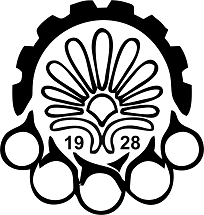

## Amirkabir University of Technology

(Tehran PolyTechnic )

## CFD Course Final Project (First Problem)

Prepared by

## Hossein Sheikhshoaie

Supervisour 

## Dr. Hamid Naderan Tahan

Mechanical Engineering Department

2022 spring

# Problem specification

Lid driven cavity is a famous problem in which a square with three fixed edge and a moving lid solved. The flow is steady, incompressible and the fluid properties such as density and viscosity are constant. Problem object is solution with 1, 10, 100 and 500 Re number.

## Governing equations

Governing **nondimensionalized** Equations are listed below. Note that the shape of the continuity problem is changed, becaouse of the **Artificial Compressibility method,** which has been chosen to overcome the **Degenerate Equations** obstacle. 

Momentom equation in x direction


$$\frac{\partial u}{\partial t} + u\frac{\partial u}{\partial x} +v\frac{\partial u}{\partial y} = -\frac{\partial p}{\partial x} + \frac{1}{Re}(\frac{\partial^2 u}{\partial x^2} + \frac{\partial^2 u}{\partial y^2})$$


Momentom equation in y direction


$$\frac{\partial v}{\partial t} + u\frac{\partial v}{\partial x} +v\frac{\partial v}{\partial y} = -\frac{\partial p}{\partial y} + \frac{1}{Re}(\frac{\partial^2 v}{\partial x^2} + \frac{\partial^2 v}{\partial y^2})$$


Continuity equation, by usage of **Artificial Comperessibility** method for degenerate problem.


$$$ \frac{\partial p}{C \partial t} + \frac{\partial u}{\partial x} + \frac{\partial v}{\partial y} = 0$
$$


In which  C is the Compressibility factor, that will be explained more later.

## Physical Boundary conditions

In this famous problem, the right, left and bottom walls are fixed. however the top wall of cavity (lid) moves with the nondimensional horizontal velocity u=1. as well the vertical component of velocity is zero on the boundaries. below figure shows boundary conditions.

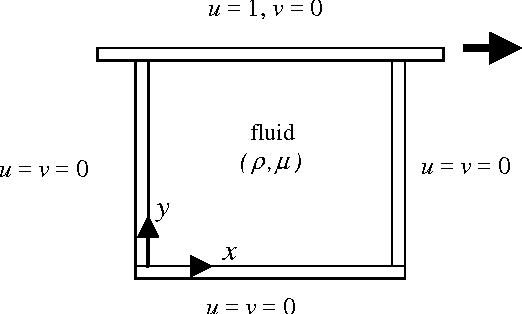

There is not any physical boundary condition for pressure, Because of the walls, but some boundary conditions will be defined in future.

## Initial conditions

The velocity components are zero everywhere on the domain, unless on the top wall of the cavity, because the boundary conditions should be considered. 

For pressure initial condition is not as important as velocity, because the continuity and mumentom equations are not related anymore in an incompressible flow. Therefore the pressure value through all the domain is one in this solution.

# Discretization

## Computational domain

Discritization of governing equations has been done on the full** staggered mesh grid**, which prevents **Cheker Board problem, **by **finite volume method**. For first order spatial derivatives the forward first order, and for the diffusion terms the central second order scheme have been used. Staggered domain of problem has been shown below. Black nodes belonges to the **collocated mesh grid** (main domain). Blue, green and red nodes refer to the horizontal velocity component, vertical velocity component and pressure staggered domain, respectively. 

Blue, green and yellow elements show the element which have been used for discretization of mumentom in x and y direction, as well as continuity equation. First, **staggered variables** (ustg, vstg and pstg) will be evaluated, then **colocated variables** (u ,v and p) will be calculated by interpolation.

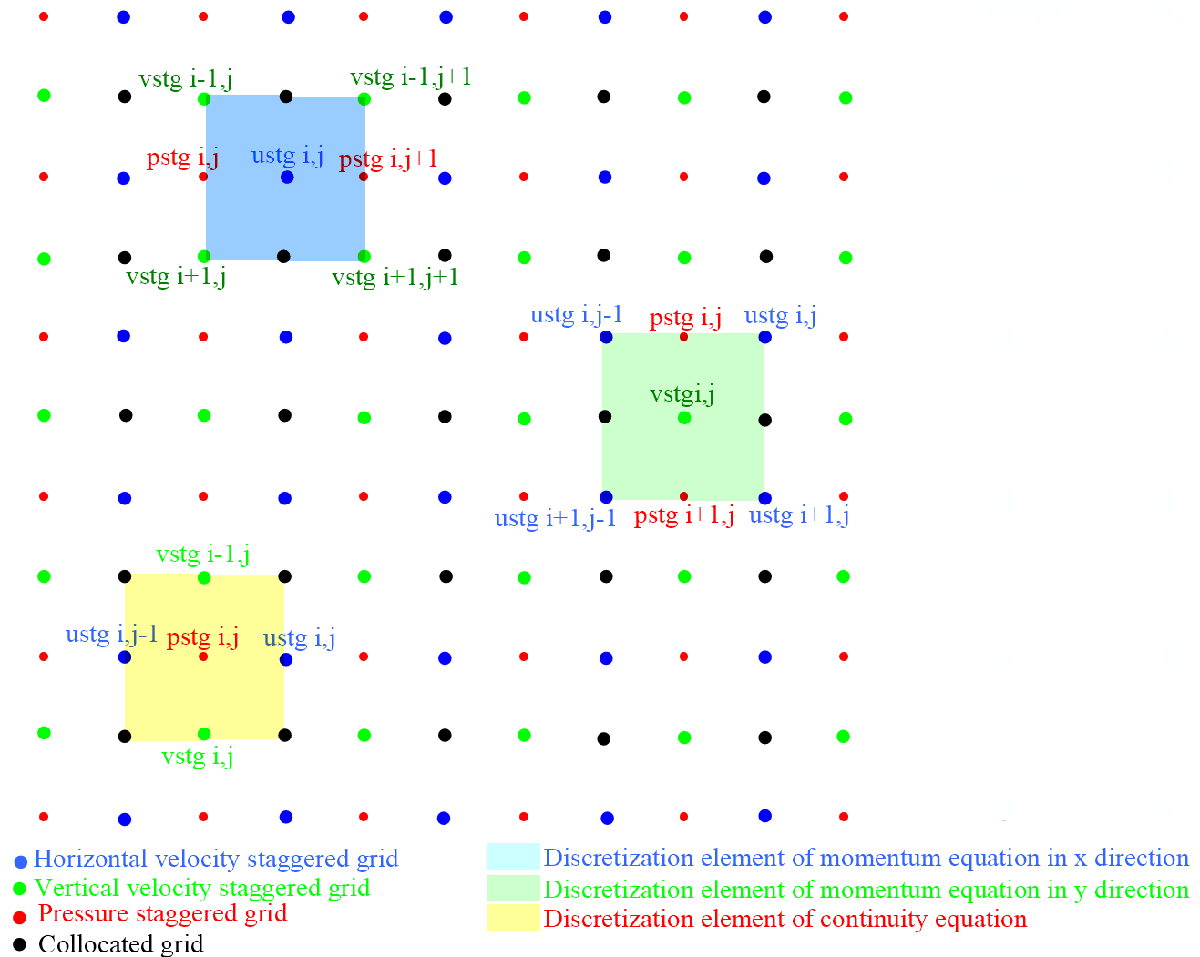

## Discretized equations

**Discritization of Momentum equation in x direction on the staggered grid**


$$ustg^{n+1}_{i,j}= ustg^{n}_{i,j} + \Delta t[-\frac{pstg_{i,j+1}-pstg_{i,j}}{\Delta x} \\+ \frac{1}{Re}(\frac{ustg_{i,j+1}-2ustg_{i,j}+ustg_{i,j-1}}{(\Delta x)^2}+\frac{ustg_{i+1,j}-2ustg_{i,j}+ustg_{i-1,j}}{(\Delta y)^2}) \\- \frac{(\frac{1}{2}(ustg_{i,j}+ustg_{i,j+1}))^2-(\frac{1}{2}(ustg_{i,j}+ustg_{i,j-1}))^2}{\Delta x} \\- \frac{\frac{1}{2}(ustg_{i,j}+ustg_{i-1,j})*\frac{1}{2}(vstg_{i-1,j}+vstg_{i-1,j+1})-\frac{1}{2}(ustg_{i+1,j}+ustg_{i,j})*\frac{1}{2}(vstg_{i,j}+vstg_{i,j+1})}{\Delta y} ]$$
  

**Discritization**$ $**momentum equation in y direction** **on the staggered grid**


$$vstg^{n+1}= vstg^{n} + \Delta t[-\frac{pstg_{i,j}-pstg_{i+1,j}}{\Delta y}\\ + \frac{1}{Re}(\frac{vstg_{i,j+1}-2vstg_{i,j}+vstg_{i,j-1}}{(\Delta x)^2}+\frac{vstg_{i+1,j}-2vstg_{i,j}+vstg_{i-1,j}}{(\Delta y)^2})\\ - \frac{(\frac{1}{2}(vstg_{i,j}+vstg_{i-1,j}))^2-(\frac{1}{2}(vstg_{i,j}+vstg_{i+1,j}))^2}{\Delta y}\\ - \frac{(\frac{1}{2}(ustg_{i,j}+ustg_{i+1,j})*\frac{1}{2}(vstg_{i,j}+vstg_{i,j+1})-(\frac{1}{2}(ustg_{i,j-1}+ustg_{i+1,j-1})*\frac{1}{2}(vstg_{i,j}+vstg_{i,j-1})}{\Delta x} ]$$


**Discretized continuity equation on the staggered grid**


$$pstg^{n+1}=pstg^{n} - C *\Delta t*[\frac{ustg_{i,j}- ustg_{i,j-1}}{\Delta x} +\frac{vstg_{i-1,j}-vstg_{i,j}}{\Delta y}]$$


clc
clear
close all

sz = [1 5];
varTypes = {'double','double','double','double','double'};
varNames = {'Grid_size','Re1','Re10','Re100','Re500'};
T = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

# Solution parameters

## Acceptable error

Most important part of the solution is done by a while loop, which must be stopped when the solution becomes convergent. Here the defined criterion is based on **continuity equation error**. Because the convergency takes place when the mass conservation is satisfied. For steady state incompressible flows, It happens when the blow equation is been stablished. 


$$$  \frac{\partial u}{\partial x} + \frac{\partial v}{\partial y} = 0$
$$


So the error on will be defined as


$$$ Continuity\, residual\,  error =\frac{\partial u}{\partial x} + \frac{\partial v}{\partial y} $
$$


In these solutions acceptable value for this error equals to $10^{-6}$.

ac_err = 10^(-4);% Acceptable error

Some paremeters such as Reynolds Number, cavity length and the velocity of the lid are already defined. Considered Reynolds are 1, 10, 100 and 500 respectivey. Both  Cavity length and lid velocity are 1. If the Re is defined as :

                                                                        
$$Re_L=\frac{UL}{\nu}$$


in which $\nu$ is the fluid static viscousity, Re is dependent to viscousity. 

L=1; %Cavity length
U=1; %Lid velocity
nu = [1 0.1 0.01 0.002]; %static viscousity

**Artificial Compressibility parameters**

The problem is steady state, so the time derivetive terms which are appeared in governing equation are applicable to prevent **degenerate of equations**. 

The degenerate state takes place when the flow is incompressible. In such problems **pressure isn't a phisycal variable anymore**. There are several approach to the mentioned problem. Here the Artificial Compressibility Method is used.  so **time step** **(**$\delta t
$**)** defenition is necessary. From governing equations and results of this project, time step dependency to Re will be clear. In order to have convergent and convenient siolutions, **there is specific time step for each Re**.  

Another important parameter is the **compressibility factor** which effect directly on the number of iterations and solution time, also it can make the solution divergent. so it must be chosen carefully. In addition its effect on solution will be changed by different Re numbers, consecuently a spicific compressibility factor is been defined for each Re too.

As mentioned for each Re numbers, special parameters are needed. So the solution is divided into four, for each Re. then one must define some arrays for diffrent Re numbers and their suitable time steps and compressibility factors (C).

Re_array = [1 10 100 500]; %Re numbers
dt_array = [0.00005 0.0001 0.001  0.0005 ]; % Related time steps
C_array = [5 2 4.5 1];%  Related artificial compressibility factors

By these arrays, solution for all Re numbers is available in one loop. 

for r=2:4 % A loop that makes solution for diffrent Re.
    Re = Re_array(1,r);
    dt = dt_array(1,r);
     C =  C_array(1,r) ;

Next important parameter of solution is the Number of nodes in each colums and rows, which specifies the **grid size (h)**. The solution must be independent to the grid size (h), so different mesh sizes have to be examined. For this purpose, a loop is defined which decreases the grid size in each iteration and compares the results of diffrent number of nodes. By this procedure the best grid size which consequences in accurate results and low computation costs such as time and memory will be chosen. 

Now by defenition of some grids in  another loop, Problem mesh with diffrent number of nodes is provided. Also grid comparison is avalable and the mesh dependency analysis can be started. 

s=6; % A loop which provides diffrent grid size.
tic    
n = (2^s)+1;%nodes number in each columns and rows 
h = L/(n-1);%mesh size

# Problem variables

**Colocated variables**

These variables are defined on collocated grid and will be evaluated at the end of solution, when the stggered variables are calculated as soon as the results become convergence. 

evaluation of this variables is done by interpolation of staggered variables.

u= zeros(n,n); % horizontal velocity component on collocated grid
v= zeros(n,n); % Vertical velocity component on collocated grid
p= ones(n,n); % pressure on collocated grid
u (1,:) = 1; % The lid boundary condition of horizontal velocity component

## Staggered variables

Staggered variables have to be defined on their staggered grid, so the dimension of their matrixes differs as well as their **boundary conditions**. So another boundary conditions related to those which had been defined earlier is necessary.  The initial values for all staggered variables is defined below. 

Its obvious that velocity components on intreior nodes are zero at first, however the horizontal velocity components of the cavity lid equal to one.  So boundary condition should be considered in the initial conditions. The lid face is in the center of first and second rows of the staggered ustg nodes, therefore below equation is extracted from interpulation


$$ustg_{(1\, , \,:)} = 2 - ustg_{(2\, , \;:)}$$


So the initial conditions will be defined as below.

% Initial conditions for Staggered variables
ustg(n+1,n)=0;
vstg(n,n+1)=0;
pstg(n+1,n+1)=1;
ustg(1,:)=2;

# Solver

As has been mentioned earlier, the solution is done through a while loop, which iterates till the  continuity acceptable error is exeeded. First the error equals to one, by this error while loop starts, the error is set zero in each loop then is calculated again . 

error = 1;
iteration_num = 0;
while error > ac_err

Discretized equations for internal nodes are written in some "for" loops, by these loops new value of variables on interior nodes in staggered grid are evaluated.  

    % x-momentum eq. - Interior
    for i = 2:n
        for j = 2:n-1
            ustg(i,j) = ustg(i,j) + dt*((1/Re)*((ustg(i+1,j) - 2*ustg(i,j) + ustg(i-1,j))/(h*h) + (ustg(i,j+1) - 2*ustg(i,j) + ustg(i,j-1))/(h*h)) - (((0.5*(ustg(i,j)+ustg(i,j+1)))^2 - (0.5*(ustg(i,j)+ustg(i,j-1)))^2)/h) - (((0.25*(ustg(i,j)+ustg(i-1,j))*(vstg(i-1,j)+vstg(i-1,j+1))) - (0.25*(ustg(i,j)+ustg(i+1,j))*(vstg(i,j)+vstg(i,j+1))))/h) + (-(pstg(i,j+1) - pstg(i,j))/h));
        end
    end
    
    % y-momentum eq. - Interior
    for i = 2:n - 1
        for j = 2:n
            vstg(i,j) = vstg(i,j) + dt*((1/Re)*((vstg(i+1,j) - 2*vstg(i,j) + vstg(i-1,j))/(h*h) + (vstg(i,j+1) - 2*vstg(i,j) + vstg(i,j-1))/(h*h)) - (((0.5*(vstg(i,j)+vstg(i-1,j)))^2 - (0.5*(vstg(i,j)+vstg(i+1,j)))^2)/h) - (((0.25*(ustg(i,j)+ustg(i+1,j))*(vstg(i,j)+vstg(i,j+1))) - (0.25*(ustg(i,j-1)+ustg(i+1,j-1))*(vstg(i,j)+vstg(i,j-1))))/h) + ( -(pstg(i,j) - pstg(i+1,j))/h));
        end
    end
    
    % Continuity eq. - Interior
    for i = 2:n
        for j = 2:n
            pstg(i,j) = pstg(i,j) - C*dt*(ustg(i,j) - ustg(i,j-1) + vstg(i-1,j) - vstg(i,j))/h;
        end
    end
   

## Staggered boundary conditions

After new variables evaluation, boundary conditions must be put in staggered variable matrixes.

It's well known that some the **staggered velocity boundary conditions** can be evaluated by **interpulation** between the collocated boundary conditions. As well other staggered nodes  are **coincident  with collocated nodes** , which results in identical boundary conditions with colocated grid. By the way staggered velocity boundary conditions are calculated.  

     % x-momentum eq. - Boundary
    ustg(1,:) = 2 - ustg(2,:);
    ustg(n + 1,:) = -ustg(n,:);
    ustg(2:n,1) = 0;
    ustg(2:n,n) = 0;    
    
    % y-momen tum eq. - Boundary
    vstg(:,1) = -vstg(:,2);
    vstg(:,n+ 1) = -vstg(:,n);
    vstg(1,2:n) = 0;
    vstg(n,2:n) = 0;
    

But staggered pressure boundary conditions differ from whatever have been mentioned, for pressure if we consider zero velocity components which happen on collocated boundary conditions, there is **no flow through those boundaries**, consequently there is **no pressure gradient** on staggered boundaries whith respect to these directions.

    % Continuity eq. - Boundary
    pstg(1,:) = pstg(2,:);
    pstg(n + 1,:) = pstg(n,:);
    pstg(:,1) = pstg(:,2);
    pstg(:,n + 1) = pstg(:,n);
    

Now the iteration's error should be calculated, for this purpose the continuity error is evaluated in these two loops.

    error = 0;
    for i = 2:n- 1
        for j = 2:n - 1
            error = error + abs((ustg(i,j) - ustg(i,j-1) + vstg(i-1,j) - vstg(i,j))/h);
        end
    end

now solution is done and iteration's counter must increase. Then while loops is ended.

    iteration_num = iteration_num + 1;
end

Staggered answers aren't the aim of solution, so that collocated answers will be evaluated by interpulating from staggered ones. Then solution will be done.

for i = 1:n
    for j = 1:n
        u(i,j) = 0.5*(ustg(i,j) + ustg(i+1,j));
        v(i,j) = 0.5*(vstg(i,j) + vstg(i,j+1));
        p(i,j) = 0.25*(pstg(i,j) + pstg(i,j+1) + pstg(i+1,j) + pstg(i+1,j+1));
    end
end

Now all the contours cann be ilustrated. A convenient grid for future figures is produced below. 

x = ((1:n)-1).*h; %Horizontal coordinate of nodes location
y = 1-((1:n)-1).*h; %Vertical coordinate of nodes location

# Mesh independency

For all numerical solution before every discussion about results, its necessary to show nodes number are enough. It means that results aren't dependent to mesh size anymore. But there is an important point, an increase in number of nodes cause increase in solution time. So convinient node number satisfies both time and accuracy considerations. Here rusults of diffrent mesh sizes for different Re numbers are presented in a table. 

T(s-5,1)={h};
T(s-5,r+1)={u((n+1)/2,(n+1)/2)};

# Validation

For validation a comparison between evaluated and benchmark date has to be done.  Benchmark data are extracted from [[1]](https://www.sciencedirect.com/science/article/pii/0021999182900584) , in  the mentioned reference velocity components u,v  on the vertical and horizontal centerlines of cavity had been presented, resprectively . Here validation is done by means of horizontal velocity data related to Re=100. Data is read from an excel table, which is filled with extracted information from [1]. Present data are related to all the nodes on the vertical centerline, however benchmark data are related to some chosen nodes on the vertical center line of cavity. It explains the diffrence between vertical location of present and benchmark results.

if Re == 100

    
figure(1000+n)
hold on;
scatter(u(:,(n+1)/2),y,'d', 'blue');

tab_data = xlsread('u_benchmark_RE100.xlsx', 'A2:B18');
benchmark_y = tab_data(:,1);
benchmark_u = tab_data(:,2);
title(['Horizontal velocity comparison for ',num2str(n),'x',num2str(n) ... 
    ,' grid',', and Re= ',num2str(Re)]);

scatter(benchmark_u, benchmark_y, 'red', 'filled');
xlabel('u');
ylabel('y');
legend('Present u', 'Benchmark u', 'location', 'southeast');

figure(1001+n);
hold on
scatter(x,v((n+1)/2,:),'d', 'green');
tab_data = xlsread('v_benchmark_RE100.xlsx', 'A4:B20');
benchmark_x = tab_data(:,1);
benchmark_v= tab_data(:,2);


scatter(benchmark_x, benchmark_v, 'red', 'filled');
xlabel('x');
ylabel('v');
legend('Present v', 'Benchmark v', 'location', 'southwest');
title(['Vertical velocity comparison for ',num2str(n),'x',num2str(n) ... 
    ,' grid',', and Re= ',num2str(Re)]);

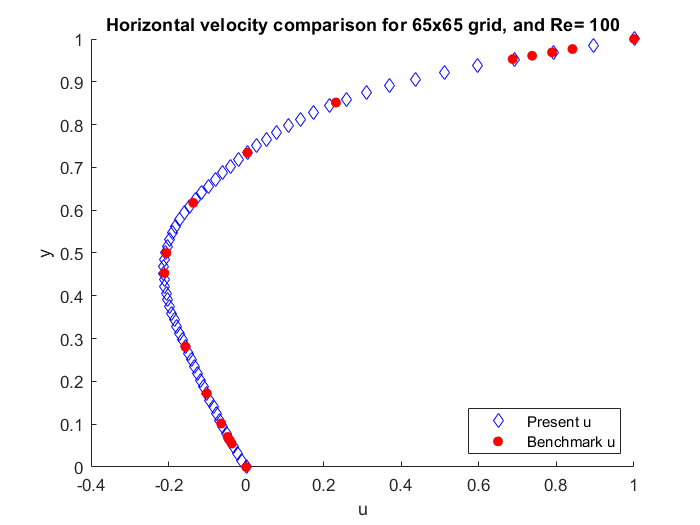

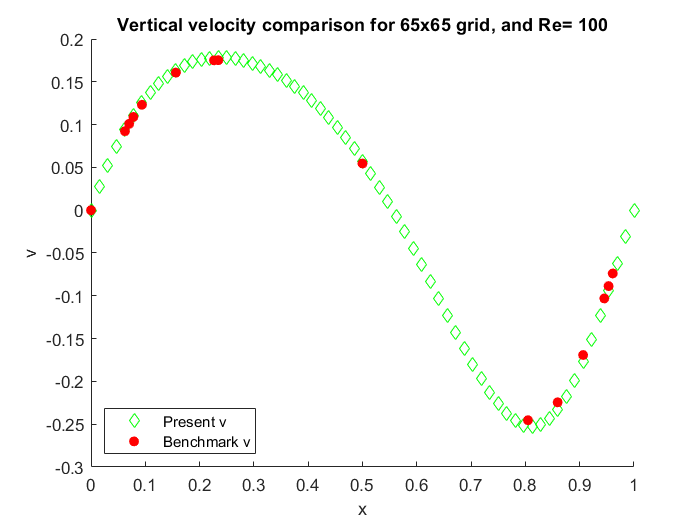

end

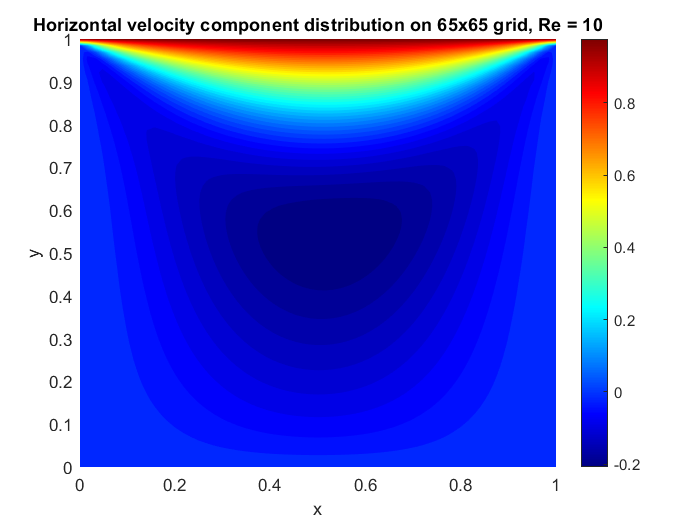

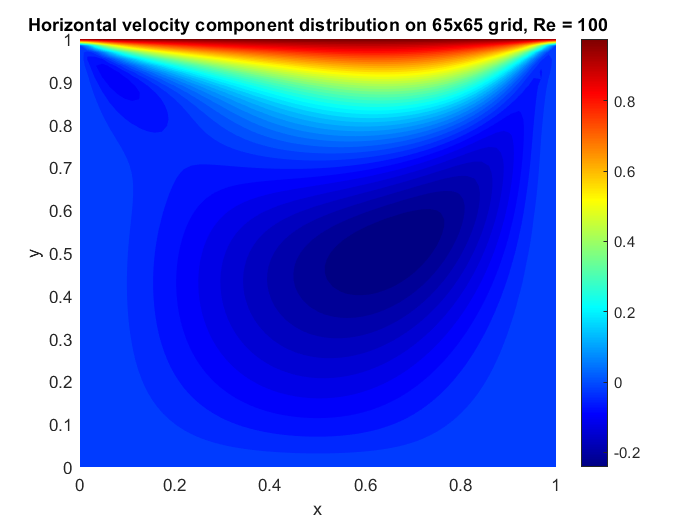

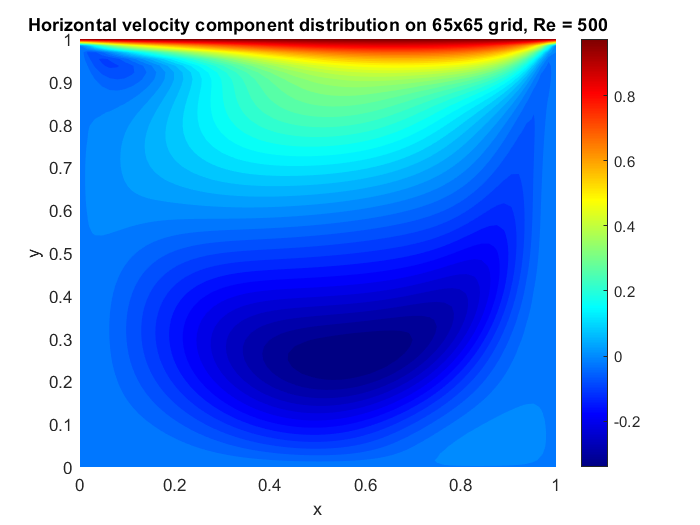

 [X,Y] = meshgrid(x,y); % Mesh grid generation for distribution cotours   
 figure(10000+Re+n);
 hold on
 contourf(X , Y ,u, 50, 'LineStyle', 'none')
 colorbar
 colormap('jet')
 xlabel('x')
 ylabel('y')
 title(['Horizontal velocity component distribution on ',num2str(n),'x',num2str(n) ...
     ,' grid, Re = ',num2str(Re)]) 

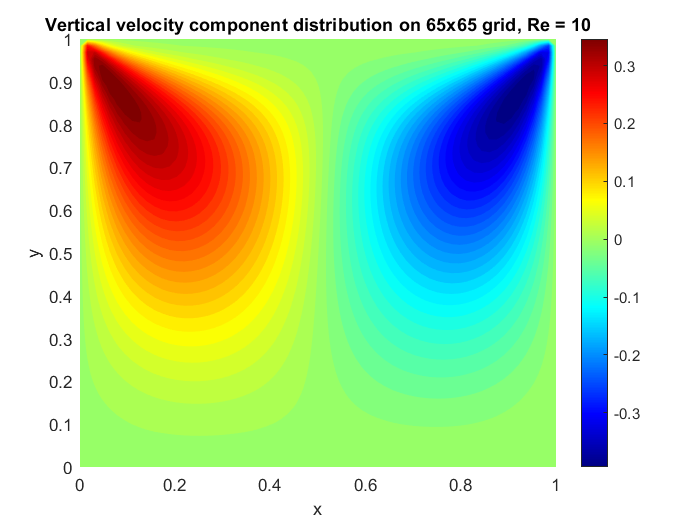

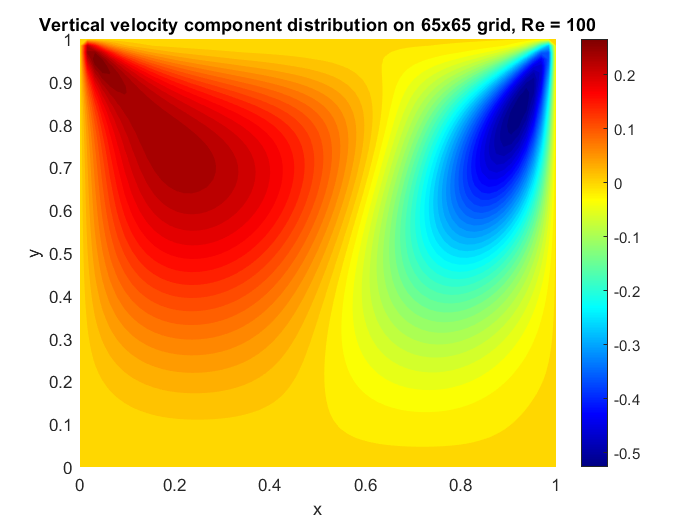

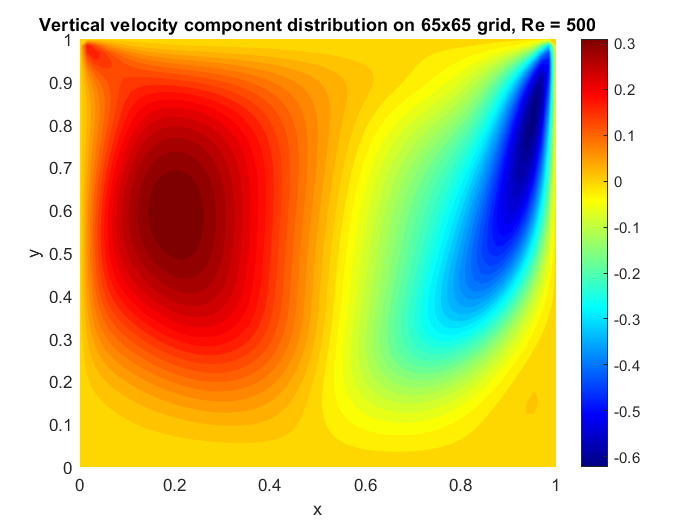

 figure(2000+Re+n);
 hold on
 contourf(X,Y,v, 50, 'LineStyle', 'none')
 colorbar
 colormap('jet')
 xlabel('x')
 ylabel('y')
 title(['Vertical velocity component distribution on ',num2str(n) ... 
     ,'x',num2str(n),' grid, Re = ',num2str(Re)])

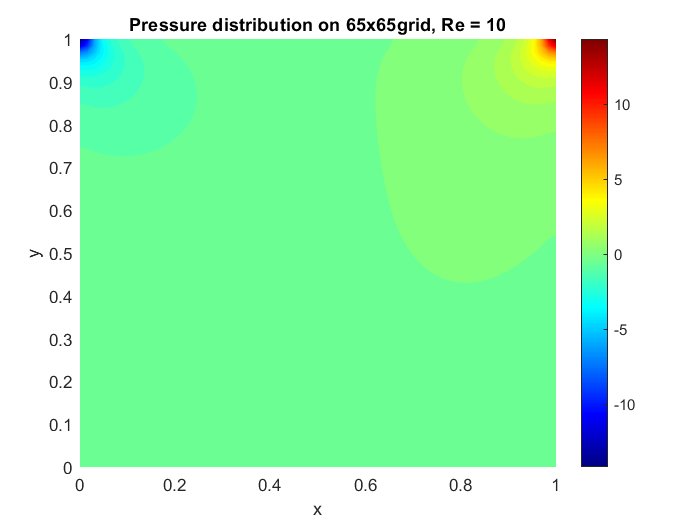

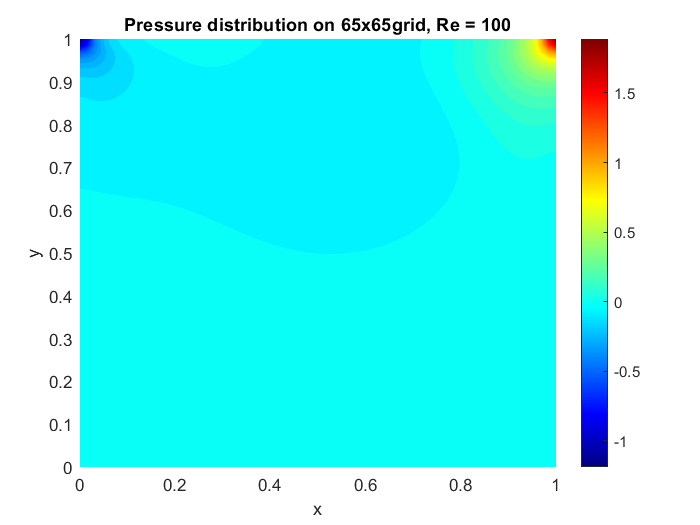

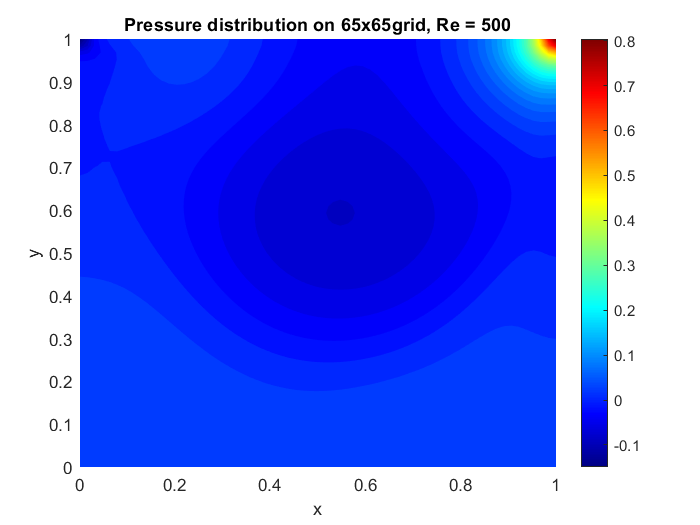

 figure(20000+Re+n);
 hold on
 contourf(X,Y,p, 50, 'LineStyle', 'none')
 colorbar
 colormap('jet')
 xlabel('x')
 ylabel('y')
 title(['Pressure distribution on ',num2str(n),'x',num2str(n),'grid, Re = ',num2str(Re)])

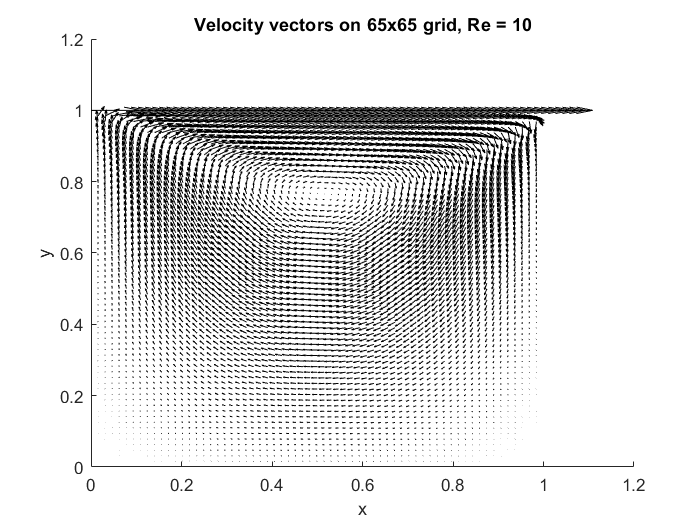

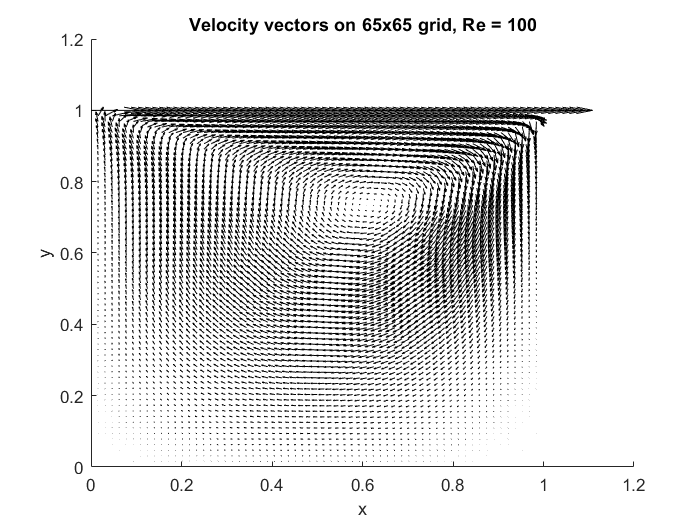

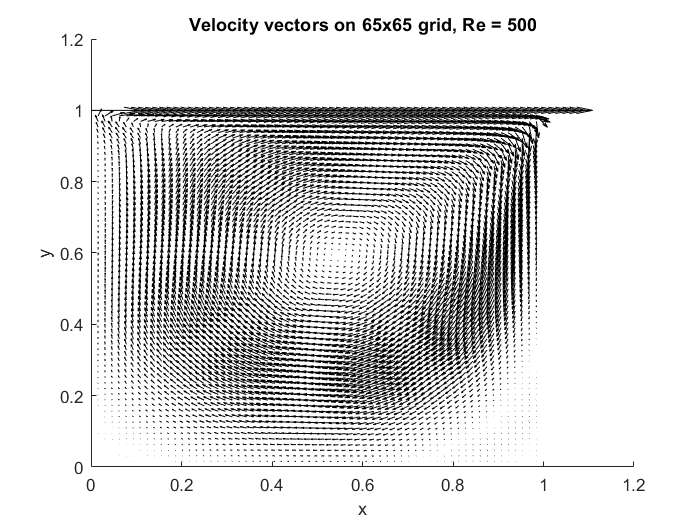

 figure(30000+Re+n)
 hold on
 quiver(X, Y, u, v, 5, 'k')
 xlabel('x')
 ylabel('y')
 title(['Velocity vectors on ',num2str(n),'x',num2str(n),' grid, Re = ',num2str(Re)])

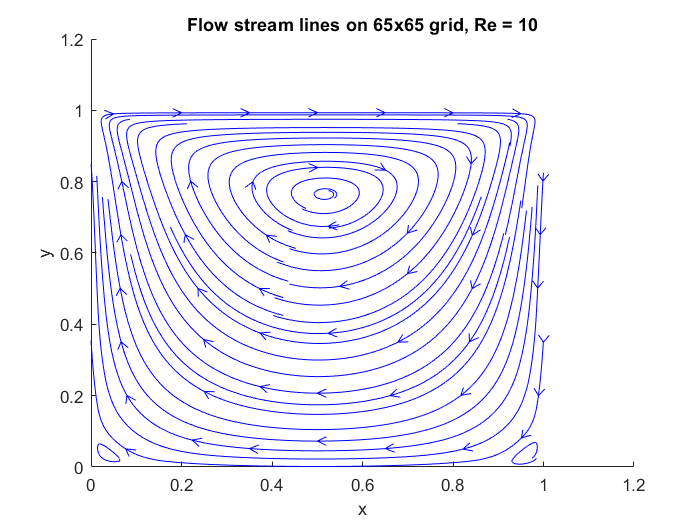

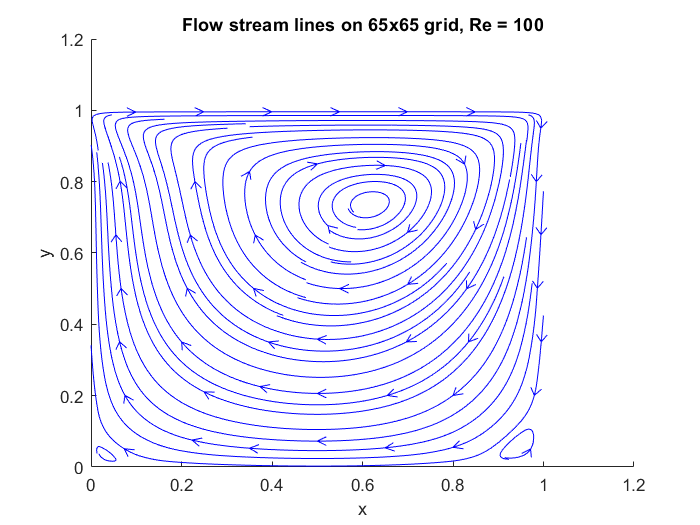

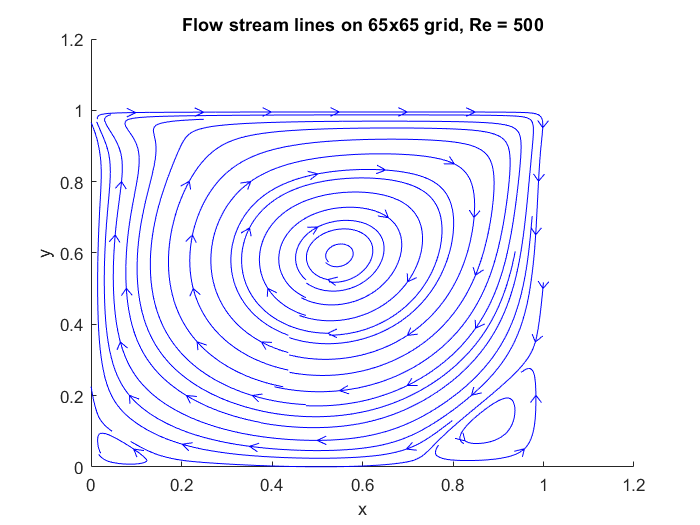

figure(40000+Re+n)
hold on
streamslice(X,Y,u,v);
xlabel('x')
ylabel('y')
title(['Flow stream lines on ',num2str(n),'x',num2str(n),' grid, Re = ',num2str(Re)])

toc

Elapsed time is 5254.926802 seconds.


Elapsed time is 2666.816672 seconds.


Elapsed time is 14943.489818 seconds.


end 

T

T = 1×5 table
    Grid_size    Re1      Re10       Re100        Re500  
    _________    ___    ________    ________    _________
    0.015625      0     -0.20484    -0.20786    -0.094991